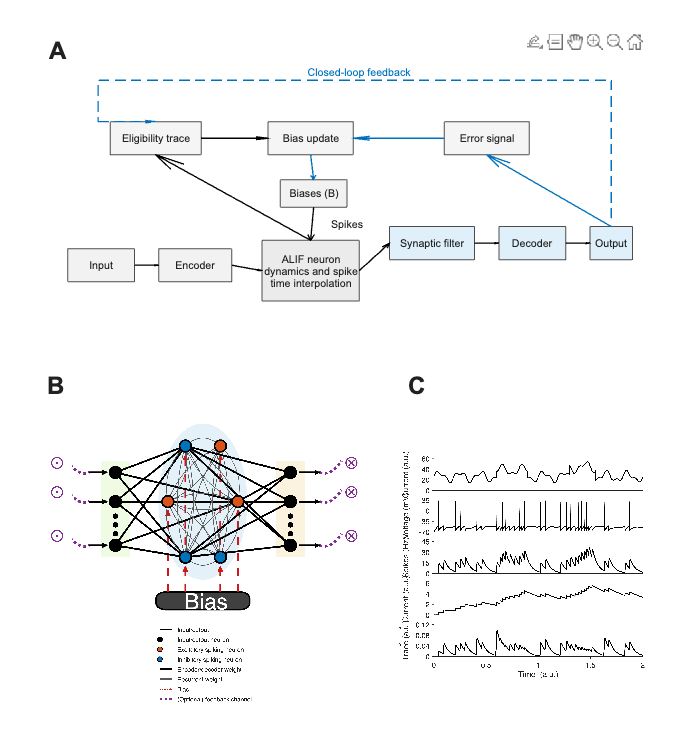

Exported manuscript flowchart figure: /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/shared/plotting/publication_figures/generated_flowchart_figure/network_learning_and_alif_publication_figure.png


%% Network Learning and ALIF Publication Figure
% Reproduces the manuscript overview layout:
% A, learning flowchart; B, recurrent network and legend; C, ALIF dynamics.

clear; clc;
repo_root = project_root();
add_project_paths(repo_root);

%% Configuration
cfg = struct();
cfg.network_script = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', ...
    'plot_network_diagram.mlx');
cfg.alif_script = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', ...
    'plot_ALIF_dynamics.mlx');
cfg.component_dpi = 500;
cfg.export_png = true;
cfg.export_dpi = 500;
cfg.figure_size_in = [8.3 9.2];
cfg.output_dir = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', ...
    'generated_flowchart_figure');
cfg.output_filename = 'network_learning_and_alif_publication_figure.png';
cfg.close_source_figures = true;
cfg.font_name = 'Arial';
cfg.panel_label_font_size = 18;
cfg.panel_label_offset = [.008 .045];
cfg.panel_label_size = [.04 .035];
cfg.flow_font_size = 8;
cfg.flow_line_width = 1.0;
cfg.flow_color = [0 0.4470 0.7410];
cfg.flow_panel_position = [.055 .565 .89 .365];
cfg.network_panel_position = [.055 .055 .49 .435];
cfg.alif_panel_position = [.585 .055 .36 .435];

%% Render the B and C source components
[network_figure, legend_figure] = render_network_components(cfg);
alif_figure = render_alif_component(cfg);
temporary_dir = tempname;
mkdir(temporary_dir);
cleanup = onCleanup(@() cleanup_temporary_files(temporary_dir)); %#ok<NASGU>
network_png = fullfile(temporary_dir, 'network.png');
legend_png = fullfile(temporary_dir, 'legend.png');
alif_png = fullfile(temporary_dir, 'alif.png');
exportgraphics(network_figure, network_png, 'Resolution', cfg.component_dpi, 'BackgroundColor', 'white');
exportgraphics(legend_figure, legend_png, 'Resolution', cfg.component_dpi, 'BackgroundColor', 'white');
exportgraphics(alif_figure, alif_png, 'Resolution', cfg.component_dpi, 'BackgroundColor', 'white');
if cfg.close_source_figures, close([network_figure; legend_figure; alif_figure]); end

%% Assemble the manuscript layout
fig = figure('Color', 'w', 'Units', 'inches', 'Position', [1 1 cfg.figure_size_in]);
draw_learning_flowchart(fig, cfg.flow_panel_position, cfg);
show_panel_image(fig, inset_position(cfg.network_panel_position, [.04 .30 .92 .60]), network_png);
show_panel_image(fig, inset_position(cfg.network_panel_position, [.04 .035 .92 .23]), legend_png);
show_panel_image(fig, inset_position(cfg.alif_panel_position, [0 .0 1 .91]), alif_png);
add_panel_label(fig, 'A', cfg.flow_panel_position, cfg);
add_panel_label(fig, 'B', cfg.network_panel_position, cfg);
add_panel_label(fig, 'C', cfg.alif_panel_position, cfg);

if cfg.export_png
    if exist(cfg.output_dir, 'dir') ~= 7, mkdir(cfg.output_dir); end
    output_file = fullfile(cfg.output_dir, cfg.output_filename);
    set(fig, 'PaperPositionMode', 'auto', 'InvertHardcopy', 'off');
    print(fig, output_file, '-dpng', sprintf('-r%d', cfg.export_dpi));
    fprintf('Exported manuscript flowchart figure: %s\n', output_file);
end

function [network_figure, legend_figure] = render_network_components(cfg)
before = findall(groot, 'Type', 'figure');
run(cfg.network_script);
created = new_figures_since(before);
if numel(created) ~= 2
    error('flowchartFigure:networkFigures', ...
        'Expected the network script to create two figures, but found %d.', numel(created));
end
network_figure = created(1);
legend_figure = created(2);
end

function alif_figure = render_alif_component(cfg)
before = findall(groot, 'Type', 'figure');
run(cfg.alif_script);
created = new_figures_since(before);
if numel(created) ~= 1
    error('flowchartFigure:alifFigure', ...
        'Expected the ALIF script to create one figure, but found %d.', numel(created));
end
alif_figure = created(1);
end

function figures = new_figures_since(before)
after = findall(groot, 'Type', 'figure');
figures = after(~ismember(after, before));
[~, order] = sort(arrayfun(@(h) h.Number, figures));
figures = figures(order).';
end

function draw_learning_flowchart(fig, position, cfg)
ax = axes('Parent', fig, 'Units', 'normalized', 'Position', position, ...
    'XLim', [0 1], 'YLim', [0 1], 'Visible', 'off');
hold(ax, 'on');
input = [.05 .17 .11 .12]; encoder = [.20 .17 .12 .12];
alif = [.37 .10 .16 .22]; bias = [.40 .44 .11 .10];
filter = [.58 .25 .14 .12]; decoder = [.76 .25 .11 .12]; output = [.91 .25 .07 .12];
eligibility = [.12 .63 .15 .12]; update = [.38 .63 .14 .12]; error_signal = [.67 .63 .14 .12];
draw_block(ax, input, 'Input', [.95 .95 .95], cfg);
draw_block(ax, encoder, 'Encoder', [.95 .95 .95], cfg);
draw_block(ax, alif, sprintf('ALIF neuron\ndynamics and spike\ntime interpolation'), [.92 .92 .92], cfg);
draw_block(ax, bias, 'Biases (B)', [.95 .95 .95], cfg);
draw_block(ax, filter, 'Synaptic filter', [.88 .94 .98], cfg);
draw_block(ax, decoder, 'Decoder', [.88 .94 .98], cfg);
draw_block(ax, output, 'Output', [.88 .94 .98], cfg);
draw_block(ax, eligibility, 'Eligibility trace', [.96 .96 .96], cfg);
draw_block(ax, update, 'Bias update', [.96 .96 .96], cfg);
draw_block(ax, error_signal, 'Error signal', [.96 .96 .96], cfg);
draw_arrow(ax, right_edge(input), left_edge(encoder), [0 0 0], '-', cfg);
draw_arrow(ax, right_edge(encoder), left_edge(alif), [0 0 0], '-', cfg);
draw_arrow(ax, right_edge(alif), left_edge(filter), [0 0 0], '-', cfg);
draw_arrow(ax, right_edge(filter), left_edge(decoder), [0 0 0], '-', cfg);
draw_arrow(ax, right_edge(decoder), left_edge(output), [0 0 0], '-', cfg);
draw_arrow(ax, bottom_edge(bias), top_edge(alif), [0 0 0], '-', cfg);
draw_arrow(ax, right_edge(eligibility), left_edge(update), [0 0 0], '-', cfg);
draw_arrow(ax, left_edge(error_signal), right_edge(update), cfg.flow_color, '-', cfg);
draw_arrow(ax, bottom_edge(update), top_edge(bias), cfg.flow_color, '-', cfg);
draw_arrow(ax, top_edge(alif), bottom_edge(eligibility), [0 0 0], '-', cfg);
draw_arrow(ax, top_edge(output), bottom_edge(error_signal), cfg.flow_color, '-', cfg);
feedback = [.945 .40; .945 .90; .10 .90; .10 .75];
plot(ax, feedback(:,1), feedback(:,2), '--', 'Color', cfg.flow_color, 'LineWidth', cfg.flow_line_width);
draw_arrow(ax, feedback(end,:), top_edge(eligibility), cfg.flow_color, '--', cfg);
text(ax, .53, .93, 'Closed-loop feedback', 'Color', cfg.flow_color, ...
    'FontName', cfg.font_name, 'FontSize', cfg.flow_font_size, 'HorizontalAlignment', 'center');
text(ax, .51, .38, 'Spikes', 'FontName', cfg.font_name, 'FontSize', cfg.flow_font_size, ...
    'HorizontalAlignment', 'center');
hold(ax, 'off');
end

function draw_block(ax, position, label, color, cfg)
rectangle(ax, 'Position', position, 'FaceColor', color, 'EdgeColor', [.30 .30 .30], 'LineWidth', .7);
text(ax, position(1) + position(3)/2, position(2) + position(4)/2, label, ...
    'FontName', cfg.font_name, 'FontSize', cfg.flow_font_size, 'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'middle', 'Interpreter', 'none');
end

function draw_arrow(ax, start_point, end_point, color, style, cfg)
delta = end_point - start_point;
quiver(ax, start_point(1), start_point(2), delta(1), delta(2), 0, ...
    'Color', color, 'LineStyle', style, 'LineWidth', cfg.flow_line_width, 'MaxHeadSize', .55);
end

function point = left_edge(position), point = [position(1), position(2)+position(4)/2]; end
function point = right_edge(position), point = [position(1)+position(3), position(2)+position(4)/2]; end
function point = top_edge(position), point = [position(1)+position(3)/2, position(2)+position(4)]; end
function point = bottom_edge(position), point = [position(1)+position(3)/2, position(2)]; end

function position = inset_position(parent, local)
position = [parent(1)+local(1)*parent(3), parent(2)+local(2)*parent(4), ...
    local(3)*parent(3), local(4)*parent(4)];
end

function show_panel_image(fig, position, filename)
ax = axes('Parent', fig, 'Units', 'normalized', 'Position', position);
image(ax, imread(filename));
axis(ax, 'image');
axis(ax, 'off');
end

function add_panel_label(fig, label, panel_position, cfg)
position = [panel_position(1) + cfg.panel_label_offset(1) * panel_position(3), ...
    panel_position(2) + panel_position(4) - cfg.panel_label_offset(2) * panel_position(4), ...
    cfg.panel_label_size];
annotation(fig, 'textbox', position, 'String', label, 'EdgeColor', 'none', ...
    'FontName', cfg.font_name, 'FontSize', cfg.panel_label_font_size, ...
    'FontWeight', 'bold', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle');
end

function cleanup_temporary_files(temporary_dir)
if exist(temporary_dir, 'dir') == 7, rmdir(temporary_dir, 's'); end
end
